Collected 16969 points


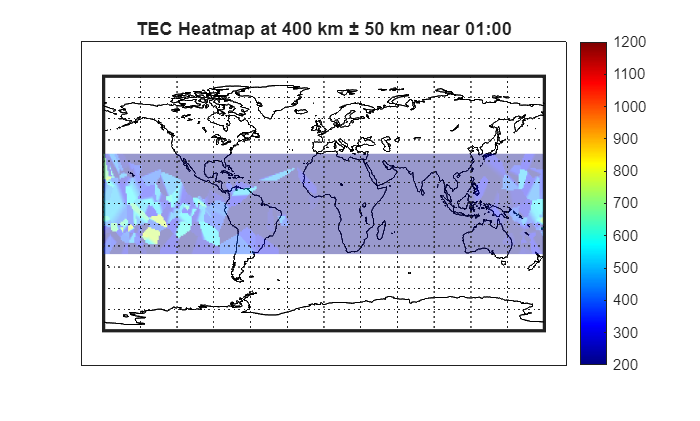

Collected 15287 points


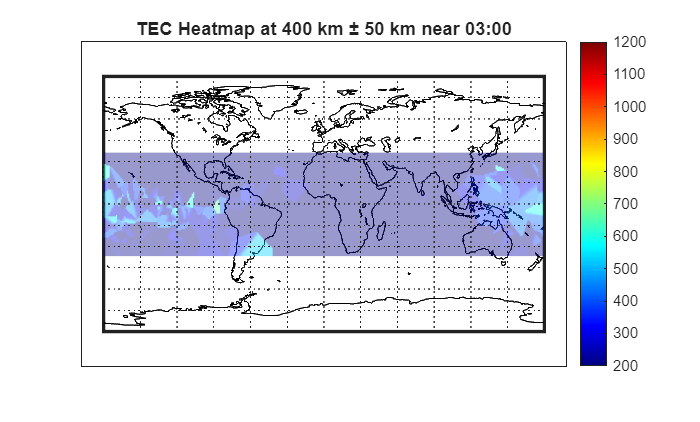

Collected 13202 points


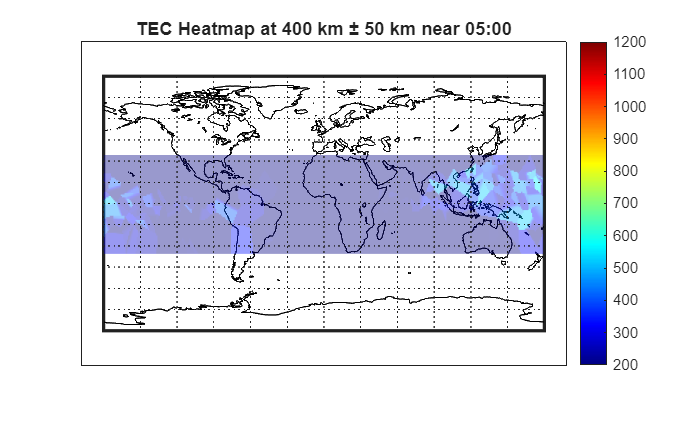

Collected 18828 points


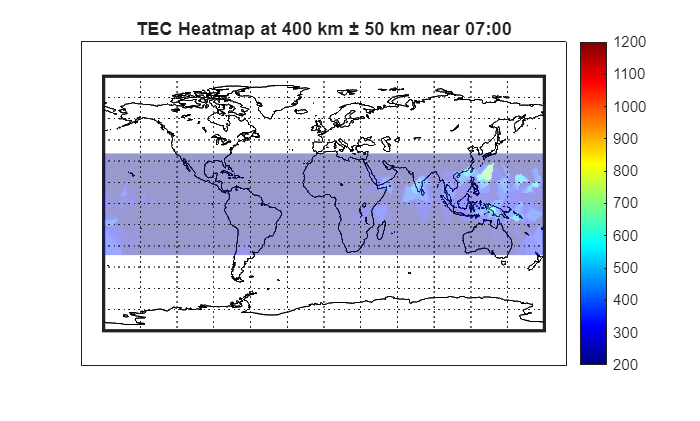

Collected 12105 points


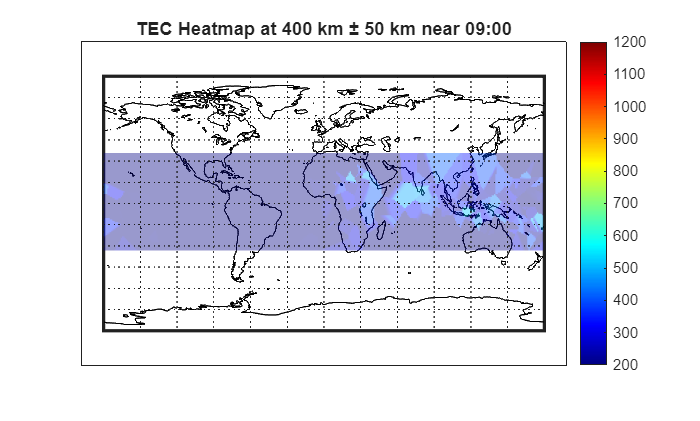

Collected 316 points


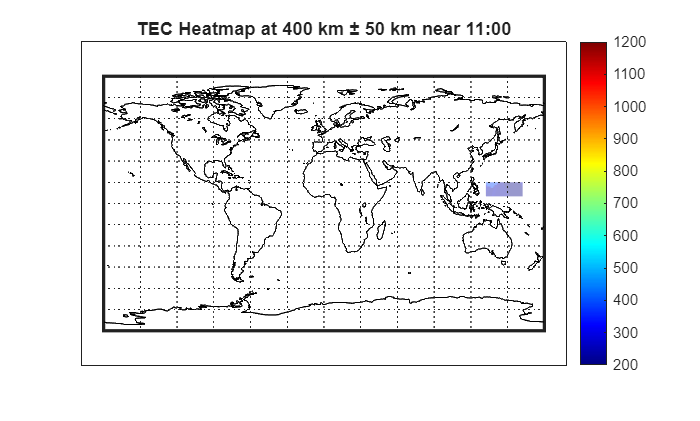

% PLOT_TEC_HEATMAP_GRID - assign nearest TEC value to a 2D lat/lon grid and plot

target_altitude = 400;
alt_tolerance = 50;
for target_hour = 1:2:23
%target_hour = 20;
target_minute = 00;
time_tolerance = 60;
grid_res = 1;

%Collect valid points
all_lat = [];
all_lon = [];
all_TEC = [];
LatGrid = [];
LonGrid = [];
TECGrid = [];
target_total_minutes = target_hour*60 + target_minute;

for i = 1:length(COSMIC_data)
    ALT = COSMIC_data{i}.MSL_alt(:);
    TEC = COSMIC_data{i}.TEC_cal(:);
    LAT = COSMIC_data{i}.GEO_lat(:);
    LON = COSMIC_data{i}.GEO_lon(:);
    
    file_total_minutes = COSMIC_data{i}.hour*60 + COSMIC_data{i}.minute;
    
    idx = abs(ALT - target_altitude) <= alt_tolerance & ...
          abs(file_total_minutes - target_total_minutes) <= time_tolerance & ...
          ~isnan(TEC) & ~isnan(LAT) & ~isnan(LON);
      
    if any(idx)
        all_lat = [all_lat; LAT(idx)];
        all_lon = [all_lon; LON(idx)];
        all_TEC = [all_TEC; TEC(idx)];
    end
end

if isempty(all_lat)
    warning('No points found for this altitude/time window.');
    return
end

% Build 2D grid nearest neighbor
lat_vec = (min(all_lat):grid_res:max(all_lat))';
lon_vec = (min(all_lon):grid_res:max(all_lon))';
[LatGrid, LonGrid] = ndgrid(lat_vec, lon_vec);
TECGrid = nan(size(LatGrid));

for r = 1:size(LatGrid,1)
    for c = 1:size(LatGrid,2)
        distances = (all_lat - LatGrid(r,c)).^2 + (all_lon - LonGrid(r,c)).^2;
        [~, idx_min] = min(distances);
        TECGrid(r,c) = all_TEC(idx_min);
    end
end

%Plot using Mapping Toolbox
fprintf('Collected %d points\n', length(all_lat));
if any(isnan(TECGrid(:)))
    fprintf('NaN in data\n')
end

figure
clf 
drawnow
% Create projected map axes
axesm('eqdcylin', ...
      'MapLatLimit', [-90, 90], ...
      'MapLonLimit', [-180, 180], ...
      'Frame','on','Grid','on')

% Add coastlines
load coastlines
geoshow(coastlat, coastlon, 'Color', 'black')

hold on

% Plot the 2D TEC grid
h = pcolorm(LatGrid, LonGrid, TECGrid);


set(h, 'FaceAlpha', 0.4) 
clim([200, 1200])
colormap("jet")
colorbar
title(sprintf('TEC Heatmap at %.0f km ± %.0f km near %02d:%02d', ...
    target_altitude, alt_tolerance, target_hour, target_minute))

hold off
end